#### `Copyright (C) 2024 Borja Imaz Lueje`

`License = GPL-3.0-or-later`

# 

# PRACTICA 3. DISEÑO DE FILTROS.

Práctica relativa al análisis y diseño de algunos ejemplos de filtros digitales, del tipo FIR e IIR. Todos ellos tienen por objetivo eliminar la presencia de un tono en la señal de voz, con lo cual se busca un filtro con respuesta elimina banda (Notch).

***NOTA: ****En este fichero se incluyen especialmente líneas de código Matlab que facilitan el desarrollo de la práctica, si bien su compresión y las preguntas del guión deben ser razonadas por el estudiante.*

## **PARTE 1.** Análisis de la secuencia de entrada.

En primer lugar importamos el fichero.

[mySpeech, fs] = audioread('voz.wav');

Con el siguiente comando, escucharíamos la señal de voz:

% soundsc(mySpeech);

Vamos a ver ahora como es esta señal.

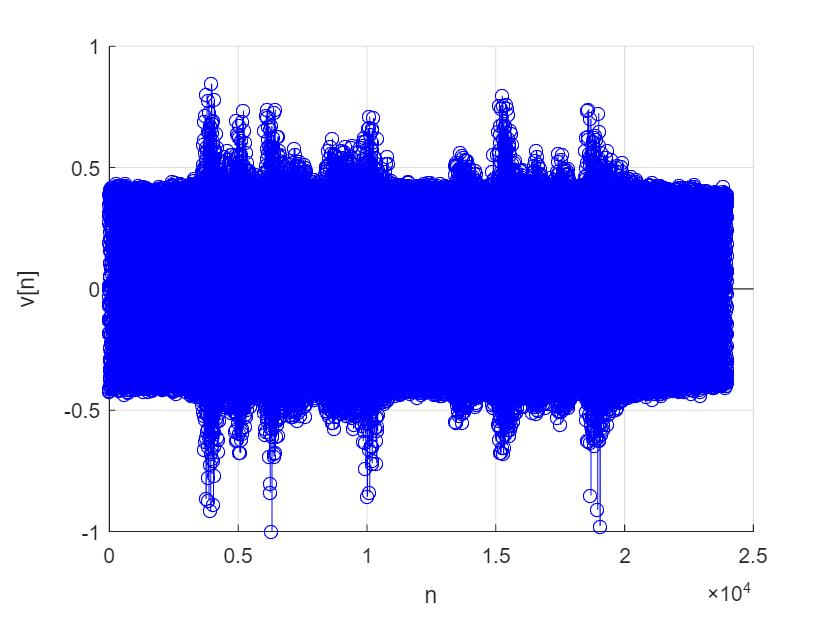

figure
hold on; grid on;
n = 0:length(mySpeech)-1;
stem(n,mySpeech,'b')
xlabel('n')
ylabel('v[n]')

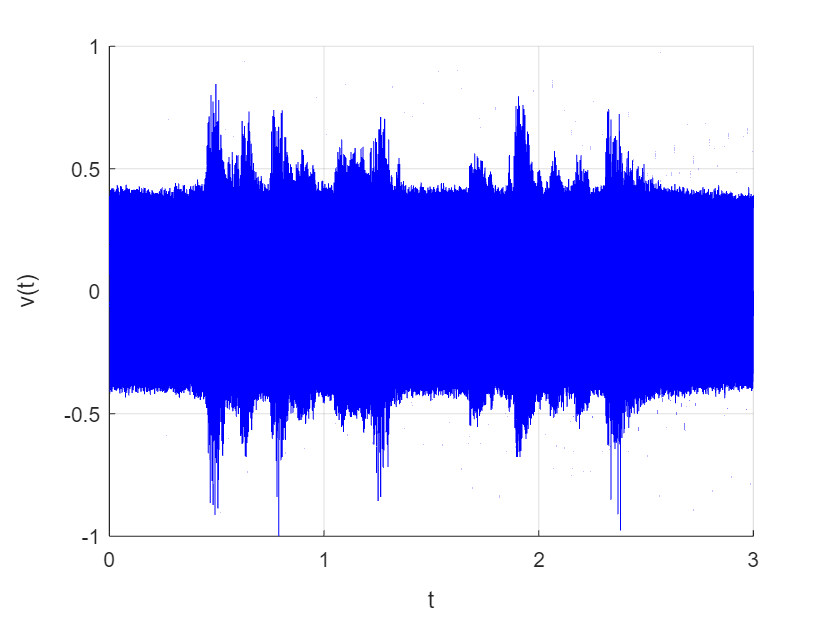


% Si quisiesemos representar la señal en tiempo:
figure
hold on; grid on;
t = n/fs; % De acuerdo con la ec. t =nTs.
plot(t,mySpeech,'b')
xlabel('t')
ylabel('v(t)')

Vamos a quedarnos de toda la señal con dos trozos: uno con presencia de voz y otro sin presencia de voz. En vista de la señal, vemos que tiene un gran numero de muestras concentradas entre los valores 0.4 y -0.4 y ciertas zonas donde la señal sobresale. 

Cogemos un trozo de la primera parte de las señal (contenido entre -0.4 y 0.4), concretamente 512 muestras:

trozo_sinVoz = mySpeech(1:512);
% Comprobamos que es un trozo sin voz.
% soundsc(trozo_sinVoz);

Para buscar un trozo con voz, buscamos una zona donde haya valores por encima de 0.4. Desde la gráfica podemos ver que entre [3500,4512] hay voz.

trozo_conVoz = mySpeech(3500:4512);
% Comprobamos que es un trozo con voz.
% soundsc(trozo_conVoz);

Por último, vamos a representar la TF (via DFT) del tramo sin voz de la siguiente forma:

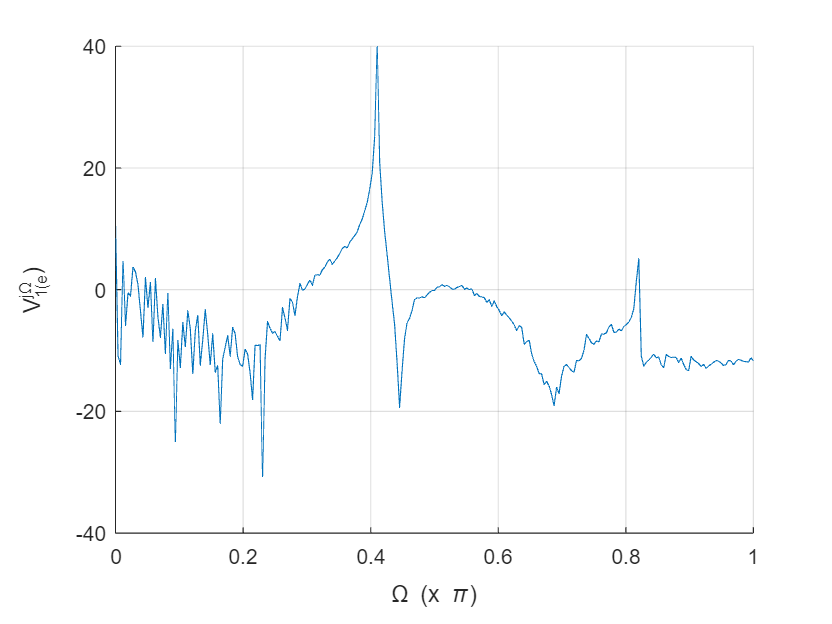

% Si no indicamos nada en el segundo parametro, la fft es de la long. de x.
N=512;
TF_trozo_sinvoz = fft(trozo_sinVoz,N); 
k = 0:length(TF_trozo_sinvoz)-1;
Omega = 2*pi*k/N;

figure
grid on; hold on;
plot(Omega/pi,20*log10(abs(TF_trozo_sinvoz)))
xlabel('\Omega (x \pi)')
ylabel('V_1(e^{j\Omega})')
xlim([0 1]);

Con esta gráfica podemos calcular la frecuencia del tono interferente

## **PARTE 2. ****Especificaciones del filtro.**

Se busca un filtro con respuesta de elimina banda, centrado en la frecuencia del tono interferente. Evaluaremos diferentes implementaciones, quedandonos con el que aporte una señal de voz mas limipia.

Primero representamos la TF del trozo de señal sin voz.

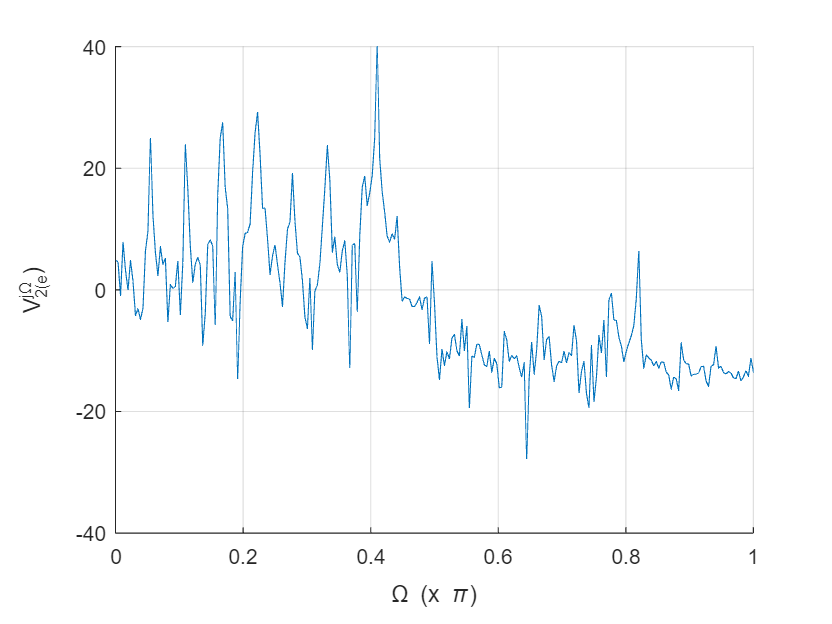

TF_trozo_convoz = fft(trozo_conVoz,N); 

figure
grid on; hold on;
plot(Omega/pi,20*log10(abs(TF_trozo_convoz)))
xlabel('\Omega (x \pi)')
ylabel('V_2(e^{j\Omega})')
xlim([0 1]);

A partir de esta gráfica y viendo los diferentes tipos de respuesta en frecuencia (tema 7 diap. 17), podemos definir los siguientes parametros:

Wp1 = 0.3789; Ws1 = 0.394531;
Ws2 = 0.4336; Wp2 = 0.453125; 
delta1 =  0.3;
delta2 = 0.0009;

Definimos:

Rp = 20*log10(1-delta1);
Rs = 20*log10(delta2);
W_i = [0 Wp1 Ws1 Ws2 Wp2 1];
H_i = [Rp Rp Rs Rs Rp Rp];

Y representamos la respuesta del filtro:

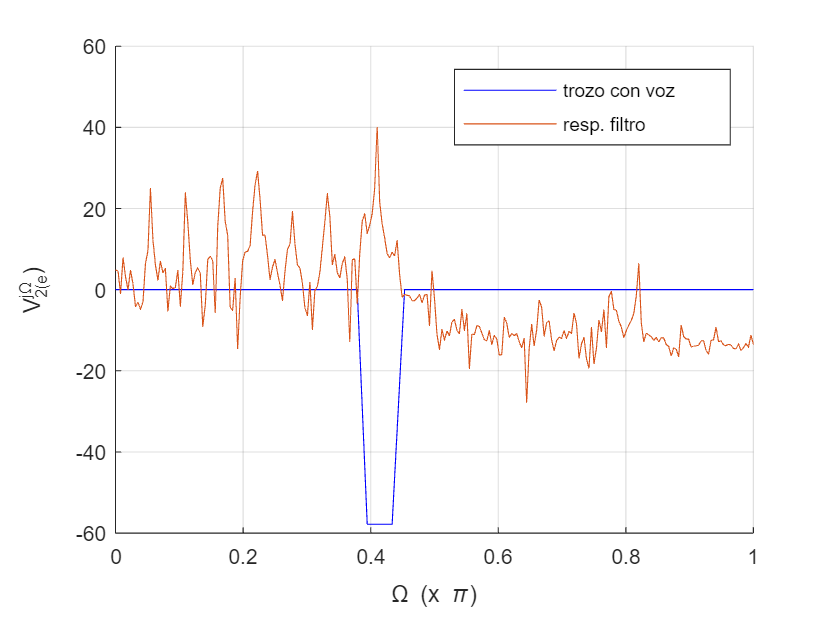

figure
hold on; grid on;
plot(W_i,H_i-max(H_i),'b')
plot(Omega/pi,20*log10(abs(TF_trozo_convoz)))
xlabel('\Omega (x \pi)')
ylabel('V_2(e^{j\Omega})')
xlim([0 1]);
legend('trozo con voz','resp. filtro')

## PARTE 3. Diseño del filtro IIR.

Se pretende diseñar un filtro IIR acorde a las especificaciones del filtro rechaza banda, siguiendo el método de Chebyshev tipo II.

Wp = [Wp1 Wp2];
Ws = [Ws1 Ws2];
[n, Wn] = cheb2ord(Wp,Ws,Rp,-Rs);

Acorde a la doc. del filtro, n indica el menor orden del filtro. Este parametro lo utilizaremos para calcular los coeficientes del filtro.

[b,a] = cheby2(n,-Rs,Ws,'stop'); % Coeficientes.

Una vez calculados los coeficientes, vamos a calcular su función de transferencia, a traves de la función freqz

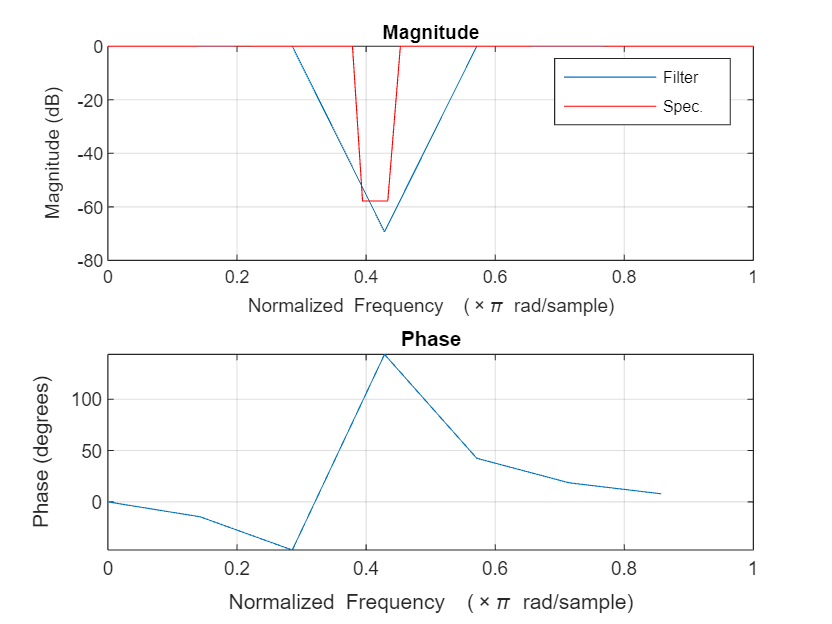

figure
freqz(b,a,n)
hold on; grid on;
plot(W_i,H_i-max(H_i),'r')
legend('Filter','Spec.')

Para calcular los polos y ceros de dicha funcion de transferencia, volvemos a aplicar cheby 2 pero ahora quedandonos con los polos y ceros.

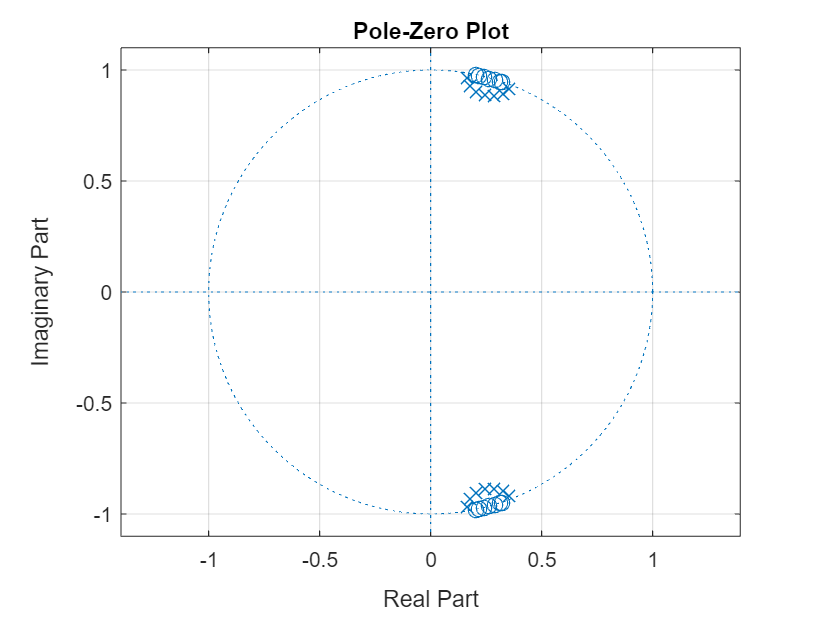

% [z,p,k] = cheby2(n,-Rs,Ws,'stop'); 
figure
hold on; grid on;
zplane(b,a)

Por último en esta parte, vamos a calcular la salida del filtro Chebyshev de tipo II diseñado y ver si ha filtrado bien la señal.

y_IIR = filter(b,a,mySpeech)

y_IIR =     0.0007
    0.0005
   -0.0002
    0.0026
   -0.0010
   -0.0009
    0.0092
   -0.0239
    0.1406
    0.2322


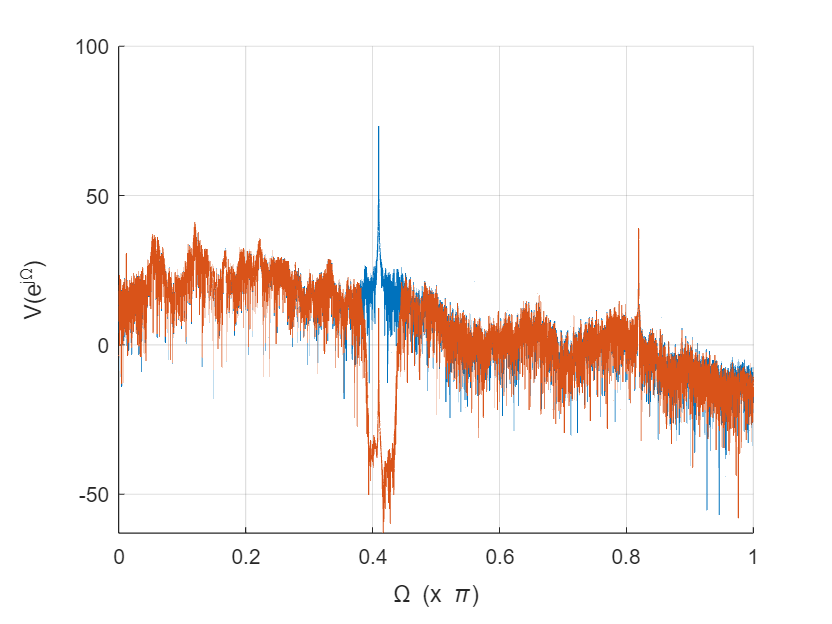


% Tono con/sin filtrado.
% soundsc(y_n);

% Si no indicamos nada en el segundo parametro, la fft es de la long. de x.
N=length(mySpeech);
TF_mySpeech = fft(mySpeech,N); 
TF_mySpeech_f = fft(y_IIR,N); 
k = 0:length(TF_mySpeech)-1;
Omega = 2*pi*k/N;

figure
grid on; hold on;
plot(Omega/pi,20*log10(abs(TF_mySpeech)))
plot(Omega/pi,20*log10(abs(TF_mySpeech_f)))
xlabel('\Omega (x \pi)')
ylabel('V(e^{j\Omega})')
xlim([0 1]);

## **PARTE 4. Filtro FIR.**

La idea ahora es diseñar un filtro FIR que se aproxime a las especificaciones de rechaza banda mediante el método de enventanado. Para usar este método hay que elegir la ventana a utilizar, calcular sus parámetros y, finalmente, enventanar la respuesta al impulso ideal.

Se ejecutan los siguientes pasos, para calcular los parametros con una ventana **Kaiser:**

bandas = [Wp1 Ws1 Ws2 Wp2]*(fs/2);
delta1 = 0.3;
delta2 = 0.0009;
[M,wn,beta,tipo]= kaiserord([bandas],[1 0 1],[delta1 delta2 delta1],fs);

Y ahora aplicando la funcion firl calculamos los coeficientes del filtro.

M = M + rem(M,2);
h=fir1(M,wn,tipo,kaiser(M+1,beta),'noscale');

Vamos a representar la respuesta al impulso del filtro diseñado.

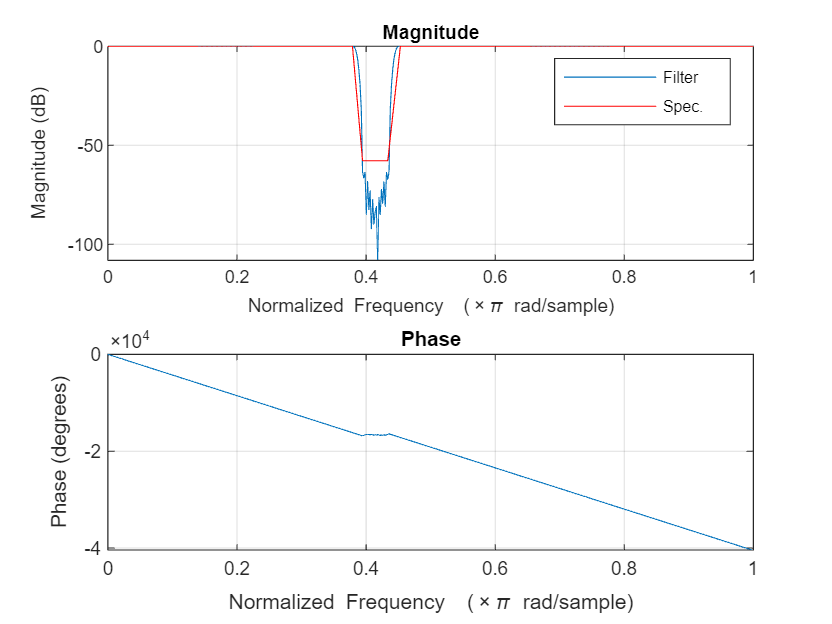

% Respuesta en frecuencia.
figure
freqz(h);
hold on; grid on;
plot(W_i,H_i-max(H_i),'r')
legend('Filter','Spec.')

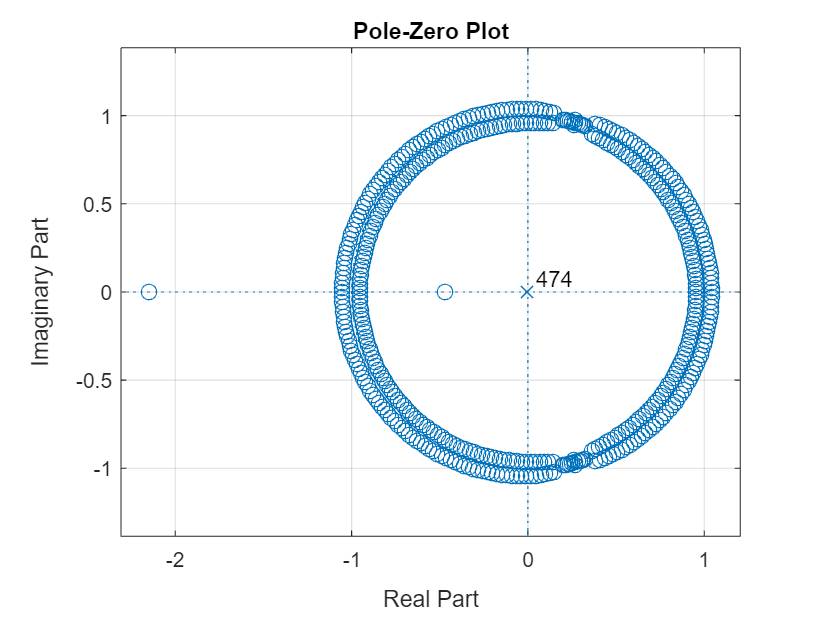


% Diagrama polos y ceros.
figure
grid on; hold on;
zplane(h);

Por último, vamos a calcular la salida empleando dicho filtro, y lo comparamos con la salida que daría el filtro IIR.

y_FIR = filter(h,1,mySpeech)

y_FIR =    -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


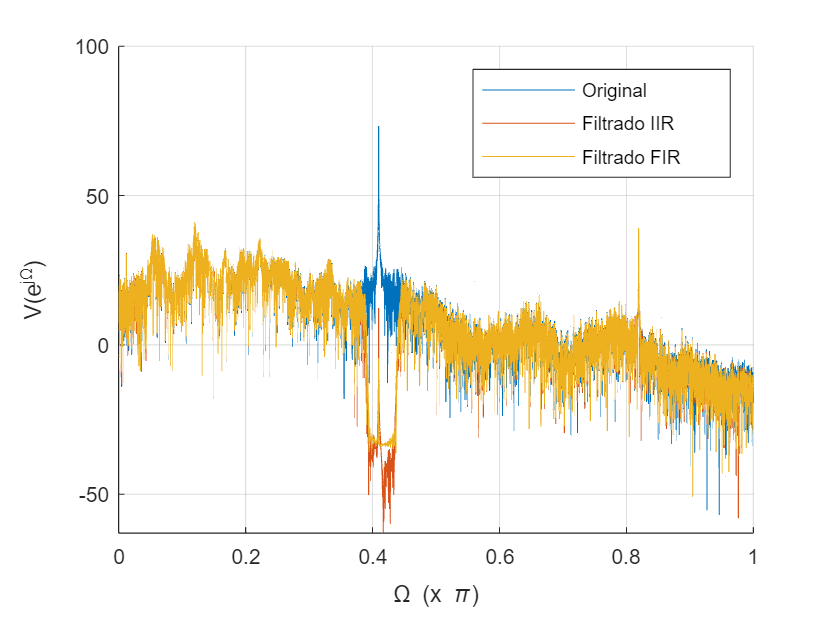


% Tono con/sin filtrado.
% soundsc(mySpeech);

% Si no indicamos nada en el segundo parametro, la fft es de la long. de x.
N=length(mySpeech);
TF_mySpeech = fft(mySpeech,N); 
TF_mySpeech_fFIR = fft(y_FIR,N); 
k = 0:length(TF_mySpeech)-1;
Omega = 2*pi*k/N;

figure
grid on; hold on;
plot(Omega/pi,20*log10(abs(TF_mySpeech)))
plot(Omega/pi,20*log10(abs(TF_mySpeech_f)))
plot(Omega/pi,20*log10(abs(TF_mySpeech_fFIR)))
xlabel('\Omega (x \pi)')
ylabel('V(e^{j\Omega})')
xlim([0 1]);
legend('Original','Filtrado IIR','Filtrado FIR')

Nos vamos a centrar ahora en un trozo de señal filtrada que tenga voz.

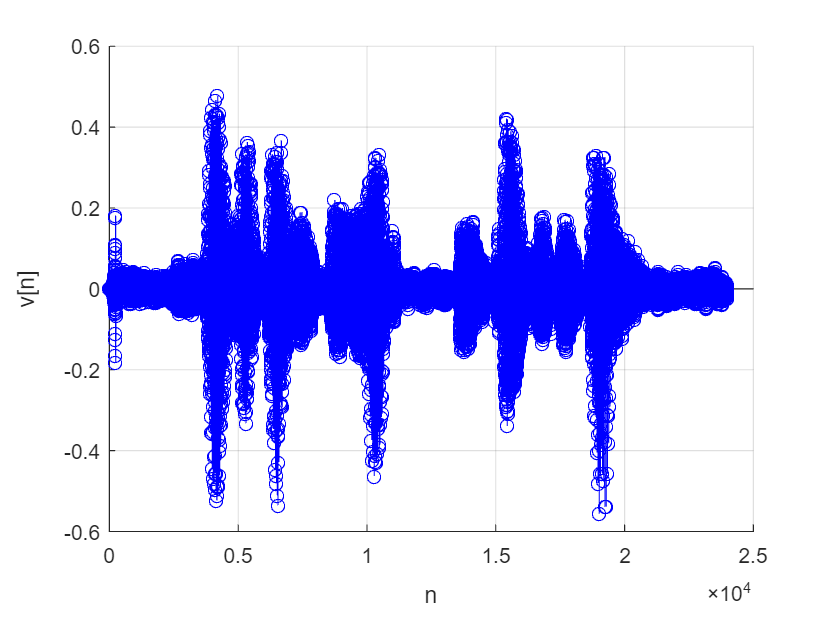

figure
hold on; grid on;
n = 0:length(y_FIR)-1;
stem(n,y_FIR,'b')
xlabel('n')
ylabel('v[n]')


trozo_conVoz_0 = mySpeech(3500:8000);
trozo_conVoz_FIR = y_FIR(3500:8000);
trozo_conVoz_IIR = y_IIR(3500:8000);
% Comprobamos que es un trozo con voz.
% soundsc(trozo_conVoz_FIR);

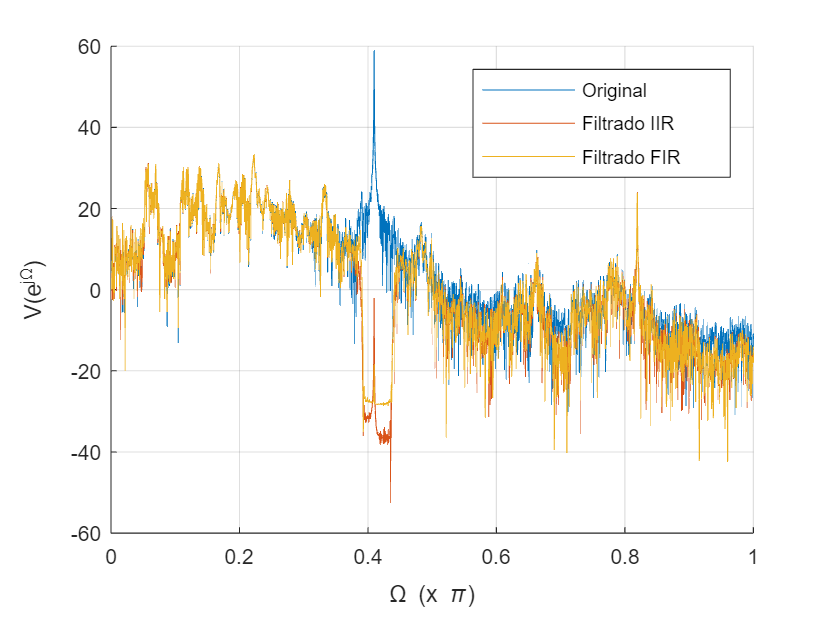


% Calculamos su TF
N=length(trozo_conVoz_FIR);
TF_trozo_voz = fft(trozo_conVoz_0,N); 
TF_mySpeech_fFIR = fft(trozo_conVoz_FIR,N);
TF_mySpeech_fFIIR = fft(trozo_conVoz_IIR,N);
k = 0:length(TF_mySpeech_fFIR)-1;
Omega = 2*pi*k/N;

figure
grid on; hold on;
plot(Omega/pi,20*log10(abs(TF_trozo_voz)))
plot(Omega/pi,20*log10(abs(TF_mySpeech_fFIIR)))
plot(Omega/pi,20*log10(abs(TF_mySpeech_fFIR)))
xlabel('\Omega (x \pi)')
ylabel('V(e^{j\Omega})')
xlim([0 1]);
legend('Original','Filtrado IIR','Filtrado FIR')